## Computer Physics

### Morse Potential EigenValues & EigenStates

#### Posprocessing & Graphing of values

*mtellezm@unal.edu.co*

*alujan@unal.edu.co*

- Energies obtained

% Open of the file
file = fopen("epsilon_values_Exact.txt", 'r');

% Scan of values on file
energies = fscanf(file, '%f', 6)'

energies =     5.7500   15.7500   23.7500   29.7500   33.7500   35.7500


% Close of file
fclose(file);

- Processing and adjust of values obtained with **FORTRAN** for comparison

clear

% Definition of intervals on program
intervals = 100000;

% Open of the file
file = fopen("psi_values.txt", 'r');

% Scan of values on file
matrix_values = fscanf(file, '%f', [7, intervals + 1])'

matrix_values =    -2.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9998    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9998    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9997    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9997    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9996    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9996    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -1.9995    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% Close of file
fclose(file);

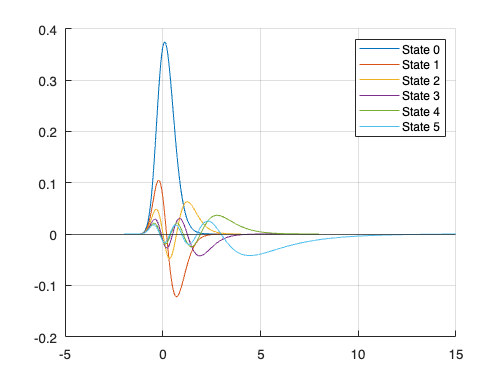

% Separation of values on psi & declaration of intervals T
phi_values = matrix_values(:, 2:7);
T_values = [linspace(-2, 3, 100001); linspace(-2, 3, 100001);
            linspace(-2, 4, 100001); linspace(-2, 6, 100001);
            linspace(-2, 8, 100001); linspace(-2, 15, 100001)]';

% Validation of correct values and characteristic silluettes
clf('reset')
hold on

plot(T_values(:, 1), phi_values(:, 1), DisplayName= 'State 0')
plot(T_values(:, 2), phi_values(:, 2), DisplayName= 'State 1')
plot(T_values(:, 3), phi_values(:, 3), DisplayName= 'State 2')
plot(T_values(:, 4), phi_values(:, 4), DisplayName= 'State 3')
plot(T_values(:, 5), phi_values(:, 5), DisplayName= 'State 4')
plot(T_values(:, 6), phi_values(:, 6), DisplayName= 'State 5')

yline(0, HandleVisibility= "off")
legend()

grid on

- Preparation of values for comparison

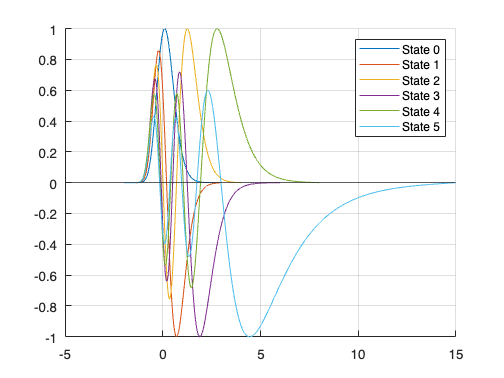

% Normalization of values
normalized_phi = zeros(size(phi_values));       % Matrix zeros like phi

for n = 1:size(phi_values, 2)
    % Max - min values
    minima = min(abs(phi_values(:, n))); maxima = max(abs(phi_values(:, n)));
    normalized_phi(:, n) = (phi_values(:, n) - minima) ./ maxima;
end

clf('reset')
hold on
plot(T_values(:, 1), normalized_phi(:, 1), DisplayName= 'State 0')
plot(T_values(:, 2), normalized_phi(:, 2), DisplayName= 'State 1')
plot(T_values(:, 3), normalized_phi(:, 3), DisplayName= 'State 2')
plot(T_values(:, 4), normalized_phi(:, 4), DisplayName= 'State 3')
plot(T_values(:, 5), normalized_phi(:, 5), DisplayName= 'State 4')
plot(T_values(:, 6), normalized_phi(:, 6), DisplayName= 'State 5')
yline(0, HandleVisibility= "off")
legend()

ylim([-1, 1])

grid on

- Teorical Energy values obtained

% Definición del parámetro lambda
lambda = 6;

% Cálculo del número máximo de n basado en lambda
n_max = floor(lambda - 0.5);

% Inicialización del vector para almacenar los eigenvalues
eigenvalues = zeros(1, n_max + 1);

% Cálculo de los eigenvalues
for n = 0:n_max
    eigenvalues(n + 1) = lambda^2 - (lambda - n - 0.5)^2;
end

% Mostrar los resultados
disp('Eigenvalues for lambda = 4:');

Eigenvalues for lambda = 4:


disp(eigenvalues);

    5.7500   15.7500   23.7500   29.7500   33.7500   35.7500



- Error obtained for energy values

Error = energies - eigenvalues;

% Display of error obtained per value
disp('Error obtained for each energy');

Error obtained for each energy


for i = 1:size(Error, 2)
    disp(['Energy for n = ', num2str(i - 1), ': ', num2str(Error(i))])
end

Energy for n = 0: 8.8818e-16
Energy for n = 1: 1.5987e-14
Energy for n = 2: 4.2633e-14
Energy for n = 3: 9.9476e-14
Energy for n = 4: 1.2079e-13
Energy for n = 5: 1.484e-07


- Teorical Psi values obtained: Exact solution

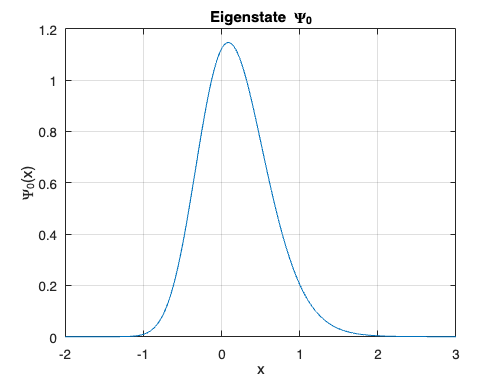

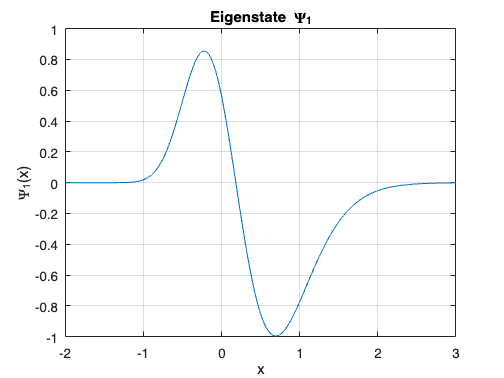

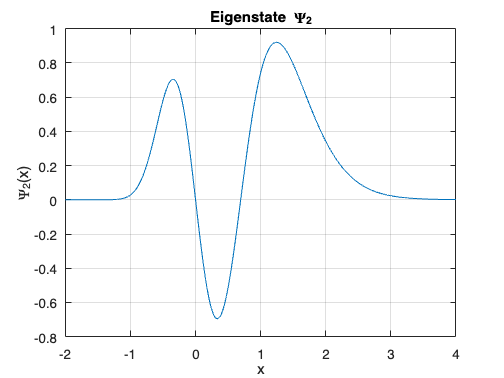

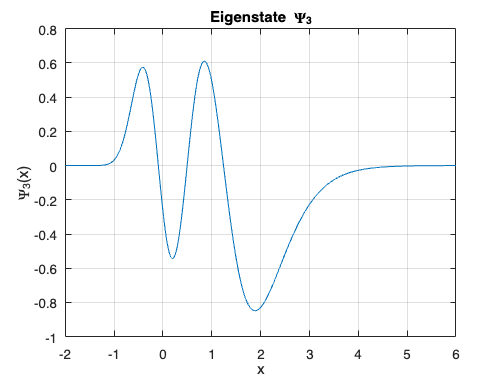

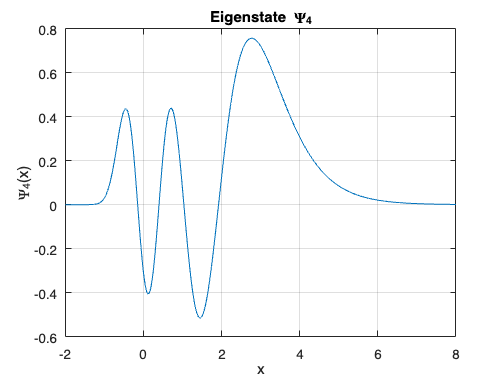

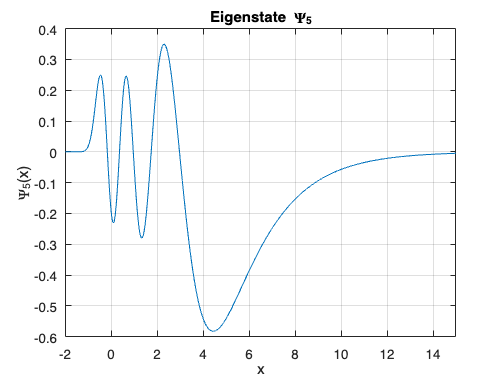

% Definición de parámetros
syms Laguerre(x)

lambda = 6; % Valor dado de lambda
xe = 0; % Puedes ajustar esto según la molécula en cuestión
n_max = floor(lambda - 0.5); % Número máximo de estados

% Definición del rango de x para el cálculo de los eigenstates
x_values = linspace(-2, 15, 100001); % Ajusta esto según sea necesario

Psi_n = zeros(size(phi_values));  % Creación nula para posterior guardado

clf('reset')

% Cálculo de los eigenstates
for n = 0:n_max

    z = 2*lambda*exp(-(T_values(:, n + 1) - xe));
    alpha = 2*lambda - 2*n - 1;
    % Factor de normalización Nn
    Nn = sqrt(factorial(n) * (alpha) / gamma(2*lambda - n));
    
    % Cálculo del polinomio generalizado de Laguerre
    Laguerre(x) = laguerreL(n, alpha, x);

    Ln = matlabFunction(Laguerre);
    Ln = Ln(z);
    
    % Función de onda del eigenstate Psi_n
    Psi_n(:, n + 1) = (-1)^(n) * Nn * z.^(lambda - n - 1/2) .* exp(-z / 2) .* Ln;
    
    % Graficar cada eigenstate
    figure;

    plot(T_values(:, n + 1), Psi_n(:, n + 1));

    title(['Eigenstate \Psi_', num2str(n)]);
    ylabel(['\Psi_', num2str(n), '(x)']);
    xlabel('x');
    xlim([-2, T_values(end, n + 1)])
    
    grid on;
end

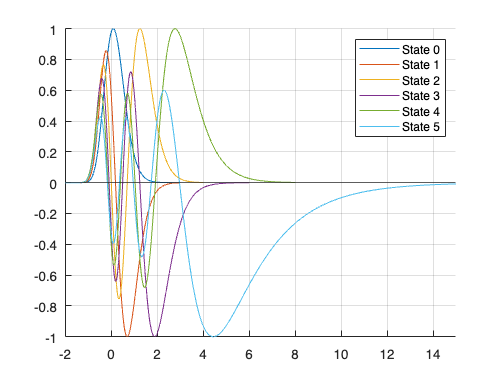

% Normalization of values
normalized_psi = zeros(size(Psi_n));       % Matrix zeros like phi

for n = 1:size(phi_values, 2)
    % Max - min values
    minima = min(abs(Psi_n(:, n))); maxima = max(abs(Psi_n(:, n)));
    normalized_psi(:, n) = (Psi_n(:, n) - minima) ./ maxima;
end

clf('reset')
hold on
plot(T_values(:, 1), normalized_psi(:, 1), DisplayName= 'State 0')
plot(T_values(:, 2), normalized_psi(:, 2), DisplayName= 'State 1')
plot(T_values(:, 3), normalized_psi(:, 3), DisplayName= 'State 2')
plot(T_values(:, 4), normalized_psi(:, 4), DisplayName= 'State 3')
plot(T_values(:, 5), normalized_psi(:, 5), DisplayName= 'State 4')
plot(T_values(:, 6), normalized_psi(:, 6), DisplayName= 'State 5')
yline(0, HandleVisibility= "off")
xlim([-2, 15])
ylim([-1, 1])
legend()
grid on

- Realicemos la comparativa de cada uno de los estados con sus valores teóricos

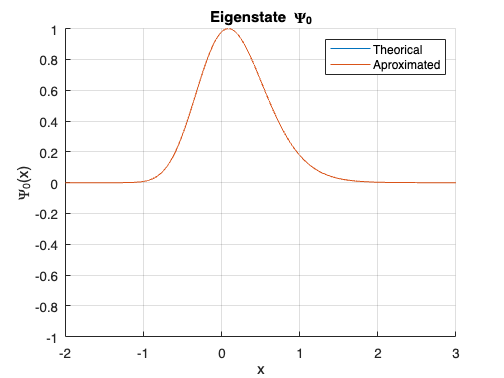

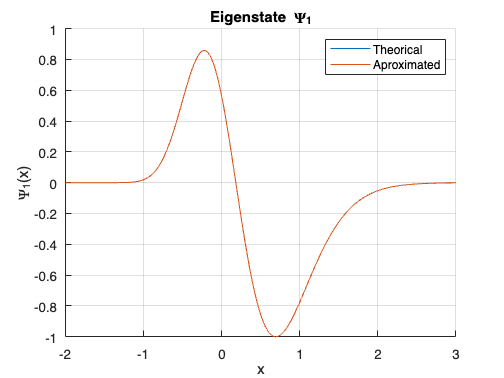

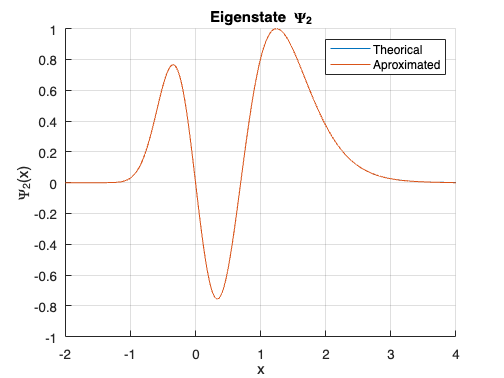

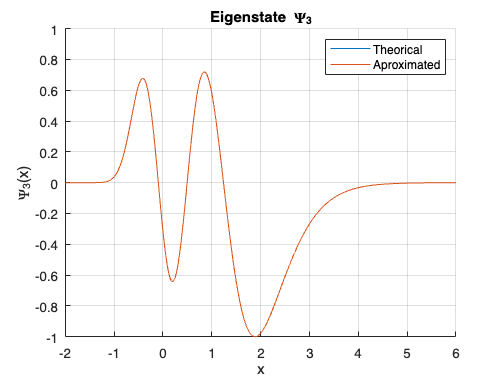

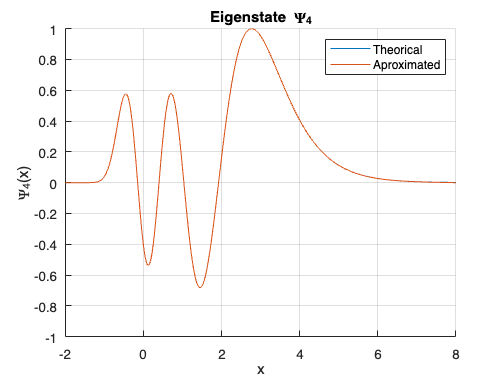

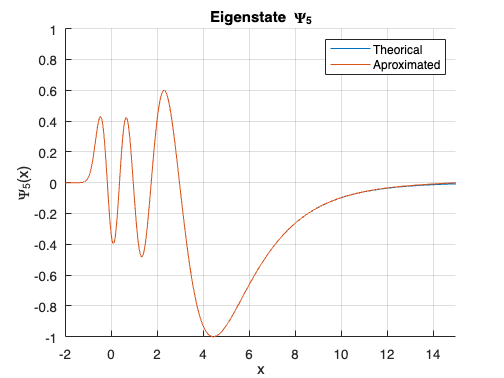

% Comparison of values
for n = 0:n_max

    % Graph per eigenvalues
    figure;

    hold on
    plot(T_values(:, n +1), normalized_psi(:, n + 1), DisplayName= 'Theorical');
    plot(T_values(:, n +1), normalized_phi(:, n + 1), DisplayName= 'Aproximated');
    hold off

    xlim([-2, T_values(end, n +1)])
    ylim([-1, 1])

    title(['Eigenstate \Psi_', num2str(n)]);
    ylabel(['\Psi_', num2str(n), '(x)']);
    legend()
    xlabel('x');

    grid on;
end

% Squared error obtained per aproximation
Error = sum((normalized_phi - normalized_psi).^2);

% Display of error obtained per value
disp('Error obtained for each state');

Error obtained for each state


for i = 1:size(Error, 2)
    disp(['Energy for n = ', num2str(i - 1), ': ', num2str(Error(i))])
end

Energy for n = 0: 7.8453e-07
Energy for n = 1: 0.0029826
Energy for n = 2: 0.0027134
Energy for n = 3: 0.00018214
Energy for n = 4: 0.006654
Energy for n = 5: 0.38171


- Finally the spectrum obtained takes the form of:

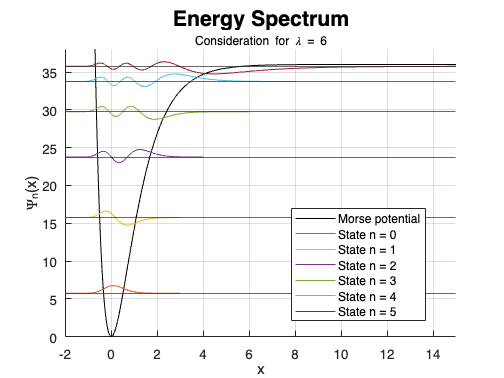

% Definition of morse potential
V = @(x) lambda^2 * (1 - exp(-(x - xe))).^2;

clf('reset')
hold on

% Common elements
fplot(V, [-2, 15], 'k', DisplayName= 'Morse potential') % Potential reference
yline(energies, HandleVisibility="off")            % Energies values references

% Eigenstates graph per energy reference
for n = 0:n_max

    plot(T_values(:, n +1), normalized_phi(:, n + 1) + energies(n + 1), ...
        DisplayName= ['State n = ', num2str(n)])
end

title('Energy Spectrum', FontSize= 16);
subtitle(['Consideration for \lambda = ', num2str(lambda)], FontSize= 9)
ylabel(['\Psi_', 'n', '(x)']);
legend(Location= 'best')
xlabel('x');

xlim([-2, T_values(end, end)])
ylim([0, lambda^2 + 2])

grid on;